# `Linear Multistep solver for differential equations + Newton's method & order of convergence analysis `

Yan D. R. Machado - Quantum Optics Laboratory - IME

### A q-step method (*q *$\ge$* 1*) is one which, $\forall$*n *$\ge$* q-1*, ${\mathit{\mathbf{u}}}_{\mathit{\mathbf{n}}+1}$ depends on ${\mathit{\mathbf{u}}}_{\mathit{\mathbf{n}}+1-\mathit{\mathbf{q}}}$, but not on the values ${\mathit{\mathbf{u}}}_k$ with *k < n+1-q*.

### 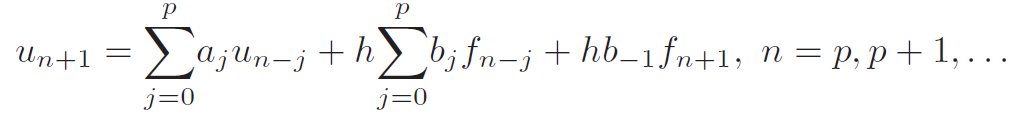 [1]           

### Those are p+1-step methods, p $\ge$ 1. For p = 0, we recover one-step methods.

### The coefficients $a_j$, $b_j$ are real and fully identify the method; they are such that for $a_p$ $\not=$ 0 or $b_j$ $\not=$ 0. If $b_{-1}$ $\not=$ 0 the method is implicit (and we need to use Newton's Method, already defined as a function in the code, to approximate solutions), otherwise its explicit.

% Parameters
f = @(t,y) [y(2)-funcao(y(1)); -y(1)]; %function you want to approximate
t0 = 0; %initial time value
T = 5; %final time value
dt = 0.1; %time interval
y_real = @(t); %analytic solution (used to plot error values)
dfy  = @(t,y) '
y0 = ;
a = ;
b = ;
b_1 = ;
u_1 = multistep_geral(a,b,b_1,t0,T,dt,f,y0,10000,1e-4,dfy)
conv_order = give_convergence_ms(f,dfy,y_real,y0,t0,T,a,b,b_1,1e-6,5000)


% General function for multistep methods
function [u] = multistep_general(a,b,b_1,t0,T,dt,f,y0,max_it,tol,dfy)
    q = length(a);
    time = t0:dt:T;
    u(:,1) = y0;
    p=q-1;
    for i = 1:q-1 
        u(:,i+1) = heun(time,i,dt,f,u(:,i));
    end

    for i = (q+1):length(time)
        sizeu = length(u);
        soma = 0;
        for j=1:p+1
            soma = soma + a(j)*u(:,i-j) + dt * b(j)*f(time(i-j),u(:,i-1));
        end
        if b_1==0
            u(:,i) = soma;
        else
            Func = @(soma,dt,b_1,f,time,i,x) x-soma-dt*b_1*(f(time(i)+dt,x));
            u(:,i)=Newton_(Func,u(:,i-1),f,dfy,time,i,b_1,dt,soma,max_it,tol);
        end
    end
    
    function [uj_next] = heun(time,j,dt,f,uj)
        uj_next=uj+dt/2*(f(time(j),uj)+f(time(j+1),uj+dt*f(time(j),uj)));
    end
    
    function [x] = Newton_(Func,x,f,dfy,time,i,b_1,dt,soma,max_it,tol)
        count = 1; erro=10;
        while erro>tol && count < max_it 
            val=(Func(soma,dt,b_1,f,time,i,x))';
            J = eye(size(x))-dt*b_1*dfy(time(i)+dt,x);
            df = (-J/val)';
            x=x+df';
            erro = norm(df,Inf);
            count = count+1;
            if count == max_it
                disp('Max iterations achieved: check parameters')
            end
        end
    end
end



function [ord] = give_convergence_ms(f,dfy,y_real,y0,t0,T,a,b,b_1,tol,itmax)
    for j = 1:5
        dt = (0.1)/(2^(j-1));
        time = t0:dt:T;
        u_real = y_real(time);
        u_method = multistep_general(a,b,b_1,t0,T,dt,f,y0,5000,1e-4,dfy);
        for i=1:length(time)-1
            error_method(i) = norm(u_real(i)-u_method(i),'inf');
        end
        error(j) = max(error_method);
        if j>1
            ord(j-1)=log2(error(j-1)/error(j));
        end
    end
end


### Below some examples of linear multistep methods and their parameter values. [1]

## I - Adam-Bashforth (AB, Explicit Adam):

### If p = 0 we recover Forward Euler.

### 2-step: $a_j$ = [1 0],  $b_j$ = [3/2 -1/2], $b_{-1}$= 0

###  

### 3-step: $a_j$ = [1 0 0], $b_j$ = [23/12  -16/12  5/12], $b_{-1}$= 0

###   

### 4-step: $a_j$ = [1 0 0 0],  $b_j$ = [55/24 -59/24 37/24 -9/24], $b_{-1}$= 0

###  

## II - Adam-Moulton (AM, Implicit Adam):

### If p = -1 we recover Backward Euler. 

### 2-step: $a_j$ = [1 0], $b_j$ = [8/12 -1/12], $b_{-1}$= 5/12

###  

### 3-step: $a_j$ = [1 0 0], $b_j$ = [19/24 -5/24 1/24], $b_{-1}$= 9/24

### 

### 4-step: $a_j$ = [1 0 0 0], $b_j$ = [646/720 -264/720 106/720 -19/720], $b_{-1}$= 251/720

### 

## III - Backward Differentiation Methods (BDF, Implicit)

### Coefficients of zero-stable BDF methods for p = 0, 1, ..., 5.

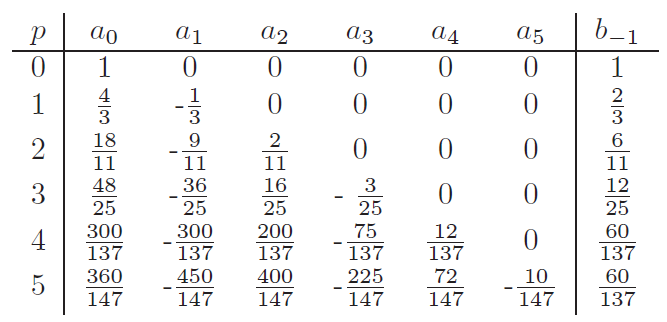

#### References:

[1] Quarteroni, A., Sacco, R., & Saleri, F. (2010). *Numerical mathematics* (Vol. 37). Springer Science & Business Media.